%QPSk
f_og = 'QPSK_pred.mat'; 
f_train = 'QPSK_data.mat'; 
f_test = 'QPSK.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 2, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9996;
msg = randi([0 3], nb, 1);
symbols = pskmod(msg, 4, pi/4);
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 

%BER
demodData_NN = pskdemod(pred, 4, pi/4); 
demodData_ideal = pskdemod(target_cp, 4, pi/4); 

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 2); %convert to bit
output_bit = int2bit(demodData_NN, 2);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

%8PSK
f_og = '8PSK_pred.mat'; 
f_test = '8PSK_100.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 3, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9996;
msg = randi([0 7], nb, 1);
symbols = pskmod(msg, 8, pi/8);
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 

%BER
demodData_NN = pskdemod(pred, 8, pi/8); 
demodData_ideal = pskdemod(target_cp, 8, pi/8); 

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 3); %convert to bit
output_bit = int2bit(demodData_NN, 3);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

%16PSK
f_og = '16PSK_pred.mat'; 
f_test = '16PSK_100.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9996;
msg = randi([0 15], nb, 1);
symbols = pskmod(msg, 16, pi/16);
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 

%BER
demodData_NN = pskdemod(pred, 16, pi/16); 
demodData_ideal = pskdemod(target_cp, 16, pi/16); 

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 4); %convert to bit
output_bit = int2bit(demodData_NN, 4);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

%8-APSK
f_og = '8APSK_pred.mat'; 
f_test = '8APSK.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9996;
M = [4 4];
radii = [0.3 1]; 
msg = randi([0 7], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 

%BER
demodData_NN = apskdemod(pred,M,radii);
demodData_ideal = apskdemod(target_cp, M, radii);

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 3); %convert to bit
output_bit = int2bit(demodData_NN, 3);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

%16-APSK
f_og = '16APSK_pred.mat'; 
f_test = '16APSK.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9996;
M = [4 12];
radii = [0.3 1]; 
msg = randi([0 15], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 

%BER
demodData_NN = apskdemod(pred,M,radii);
demodData_ideal = apskdemod(target_cp, M, radii);

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 4); %convert to bit
output_bit = int2bit(demodData_NN, 4);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

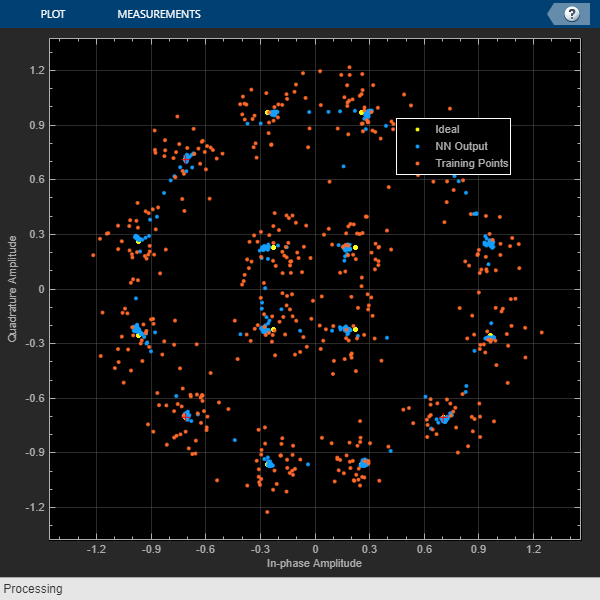

%DVBS-16APSK
rng(0);
f_og = 'DVBSAPSK_pred_SRRC_500pck.mat'; 
f_test = 'DVBSAPSK_100_SRRC_500pck.mat'; 

load(f_og); 
load(f_test);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',500, ...
    'ChannelNames', {'Ideal', 'NN Output', 'Training Points'});

awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 10); %create awgn channel object

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

nb = 9986;
M=16; 
msg = randi([0 15], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 
noisySig = awgnChan(symbols); 

constDiagram([target_cp, pred, noisySig]); 


%BER
demodData_NN = dvbsapskdemod(pred, M, 's2x'); 
demodData_ideal = dvbsapskdemod(target_cp, M, 's2x');

demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type

%calculate BER
data_bit = int2bit(demodData_ideal, 4); %convert to bit
output_bit = int2bit(demodData_NN, 4);%convert to bit

d = finddelay(data_bit,output_bit); 
errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
err = errorRate(data_bit, output_bit); %get bit error
bit_err = err(1)*100

bit_err = 0.7611